clc;
clear;

% 采样参数
fs = 10000; % 采样频率
T = 1/fs; % 采样周期
t = 0:T:0.5; % 时间向量

% 构造测试输入信号（假设为 DTMF 信号）
f1 = 697;   % 第一列频率
f2 = 770;   % 第二列频率
f3 = 852;   % 第三列频率

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 输入可调
signal =  sin(2*pi*f2*t); % 按下第1/2/3列的键
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% LTI 系统设计（巴特沃斯低通滤波器）

% 创建2阶 Butterworth 滤波器
[b1, a1] = butter(2, f1/(fs/2), 'low'); % 注意：1、matlab.butter截止频率是频率，不是圆频率；2、要做归一化
[b2, a2] = butter(2, f2/(fs/2), 'low');
[b3, a3] = butter(2, f3/(fs/2), 'low');

% 经过 LTI 系统
y1 = filtfilt(b1, a1, signal); % 输出 y1[n]
y2 = filtfilt(b2, a2, signal); % 输出 y2[n]
y3 = filtfilt(b3, a3, signal); % 输出 y3[n]
max(y1)

ans = 0.4202

max(y2)

ans = 0.5149

max(y3)

ans = 0.6102


% 判定阈值
threshold = 0.5; 

% 检测按键列
col_detected = detect_column(y1, y2, y3, threshold);
disp(['Detected Column: ', num2str(col_detected)]);

Detected Column: 2


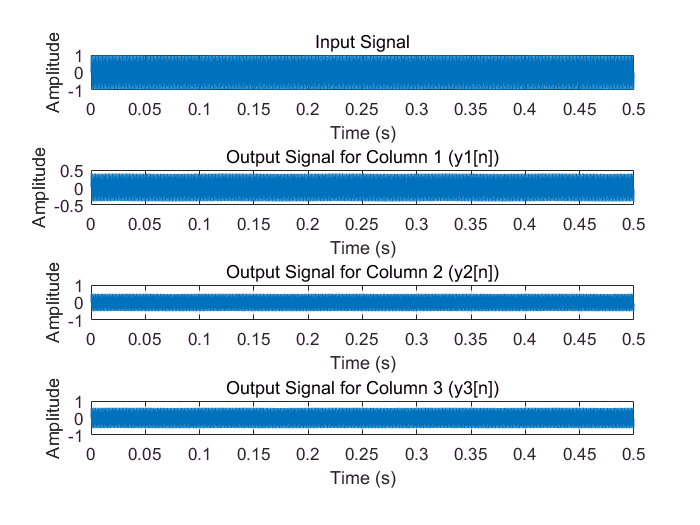


% 可视化部分
figure;

% 输入信号
subplot(4, 1, 1);
plot(t, signal);
title('Input Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 输出信号 y1
subplot(4, 1, 2);
plot(t, y1);
title('Output Signal for Column 1 (y1[n])');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 输出信号 y2
subplot(4, 1, 3);
plot(t, y2);
title('Output Signal for Column 2 (y2[n])');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% 输出信号 y3
subplot(4, 1, 4);
plot(t, y3);
title('Output Signal for Column 3 (y3[n])');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;